# DC Microgrid Simulator

clear all
close all
clc

rng(7)

numOfDGs = 4;
threshold = 0.6;

## Generate a random physical topology

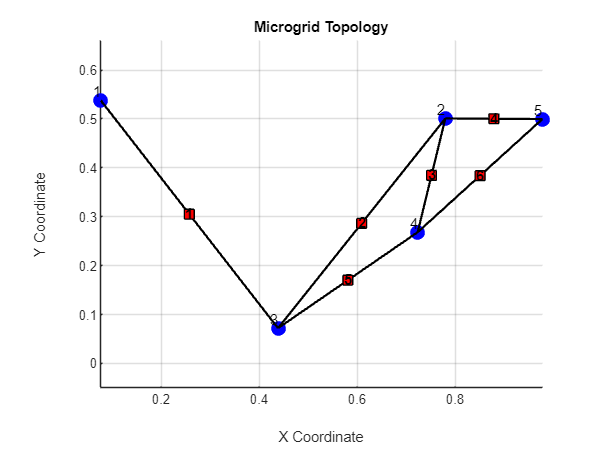

Coordinates of DGs:
    0.0763    0.9780
    0.7799    0.5385
    0.4384    0.5011
    0.7235    0.0721

Adjacency Matrix:
     0     0     1     0
     0     0     1     1
    -1    -1     0     1
     0    -1    -1     0

B_il Matrix:
     1     0     0     0
     0     1     1     0
    -1    -1     0     1
     0     0    -1    -1



coords =     0.0763    0.9780
    0.7799    0.5385
    0.4384    0.5011
    0.7235    0.0721


adjMatrix =      0     0     1     0
     0     0     1     1
    -1    -1     0     1
     0    -1    -1     0


B_il =      1     0     0     0
     0     1     1     0
    -1    -1     0     1
     0     0    -1    -1


% Input: numOfDGs and physicalDistanceThreshold

% I should be able to change "numOfDGs" and "numOfLines" variables freely
% see https://en.wikipedia.org/wiki/Random_geometric_graph
% https://github.com/shiran27/NetworkedSystemAnalysisAndControl/blob/main/Network.m
% particularly look at the function: loadARandomNetwork

% Generate a topology randomly
% Generate numOfDGs number of random points in R^2 spase using rand(1,2)
% If two generated points are closer to each other than a predefined
% threshold, they are assumed as connected. 

% Final output: of this code is B=[B_il]_{i,l} matrix and the numOfLines
% plot the graph like in Fig 2.

[coords, adjMatrix, B_il] = generateMicrogridTopology(numOfDGs, threshold)

## Generate Random set of DGs

% Initial parameter values for DGs
R0 = 0.02;      % Resistance
L0 = 0.01;      % Inductance
C0 = 0.0022;    % Capacitance
RL0 = 0.3;      % Load Resistance
Y0 = 1/RL0;     % Load Conductance

for i = 1:1:numOfDGs
    DG{i} = GenerateDG(R0,L0,C0,RL0);
    
    [PVal, KVal, LVal, nuVal, rhoVal, status] = ComputePassivityForDGs(DG{i})
end

PVal =     3.4649   11.1324   -3.6874
   11.1324   65.0377  -11.9732
   -3.6874  -11.9732   13.2548


KVal =  -146.9838   11.5819   -3.9364


LVal =  -113.3440   16.4560  -16.9638


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


PVal =     3.4851   11.1750   -3.7050
   11.1750   65.0786  -11.9888
   -3.7050  -11.9888   13.2816


KVal =  -120.2811   11.9949   -3.9745


LVal =   -92.7848   13.5461  -13.9548


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


PVal =     3.3007   10.8670   -3.5547
   10.8670   65.0547  -11.8419
   -3.5547  -11.8419   13.0524


KVal =  -130.4599   11.3147   -3.7939


LVal =  -105.4621   14.9841  -15.4182


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


PVal =     3.4072   11.0558   -3.6433
   11.0558   65.1099  -11.9283
   -3.6433  -11.9283   13.1880


KVal =  -228.5674   11.4145   -3.9237


LVal =  -178.6159   25.6626  -26.4299


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


## Generate Random Set of Lines

% Initial parameter values for Lines
Rl0 = 0.02;     % Line Resistance
Ll0 = 0.01;     % Line Inductance
numOfLines = size(B_il,2);

for l = 1:1:numOfLines
    Line{l} = GenerateLine(Rl0,Ll0);
    [PBarVal, nuBarVal, rhoBarVal, status] = ComputePassivityForLines(Line{l})
end

PBarVal = 0.0386

nuBarVal = -100.0000

rhoBarVal = 0.1137

status = logical
   1


PBarVal = 0.0529

nuBarVal = -100.0000

rhoBarVal = 0.0889

status = logical
   1


PBarVal = 0.0465

nuBarVal = -100.0000

rhoBarVal = 0.0979

status = logical
   1


PBarVal = 0.0403

nuBarVal = -100.0000

rhoBarVal = 0.0707

status = logical
   1


Clear variables unrelated

 clearvars -EXCEPT DG Line numOfDGs numOfLines B_il

## Centralized Local Controller Design

[DG,Line,statusLocalController] = centralizedLocalControlDesign(DG,Line,B_il,numOfDGs,numOfLines) % topologyMetrics may be the B matrix 

MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 60              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 56              
  Matrix variables       : 12 (scalarized: 216)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.02            
Lin. dep.  - pr

DG = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusLocalController = logical
   1


% Inside the function, youneed to solve the LMI problem in (66) and add
% local passivity information and local controller information to the DG
% and Line variables. 


## Global Controller Design

[DG,Line,statusGlobalController]=globalControlDesign(DG,Line,B_il,numOfDGs,numOfLines)

Dimensions of matrices:
C: 4  12
BarC: 12   4
H: 12  12
X_p_11: 12  12
O: 12   4
O_n: 12  12
Q_i{i}: 12  12
C: 4  12
P: 4  4
BarX_Barp_11: 4  4
X_21: 12  12
X_12: 12  12

MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 153             
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 145             
  Matrix variables       : 3 (scalarized: 1616)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator started.
Freed constraints in

DG = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusGlobalController = logical
   0
